# Reproduces all graphical analysis depicted in the paper

All sections can be ran independently. Use the switches to include or skip each section.

## Switch to true to visualize the Utility Function and Indif. Curves

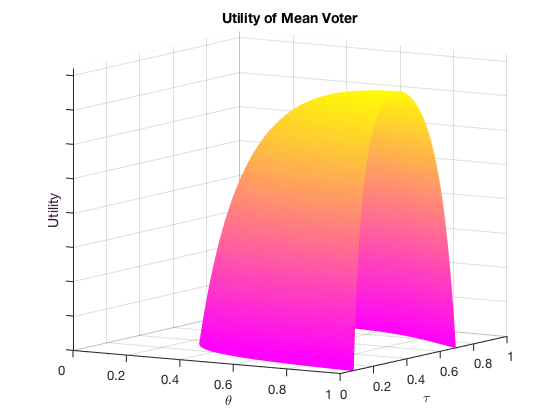

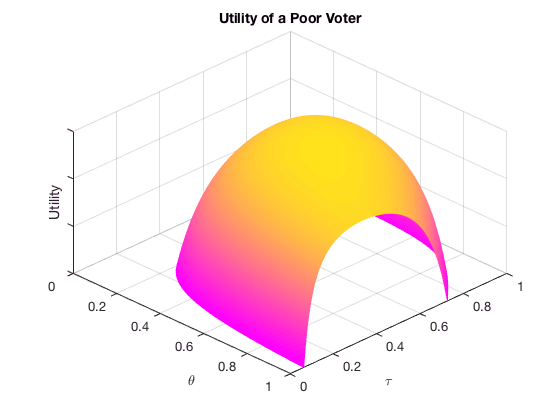

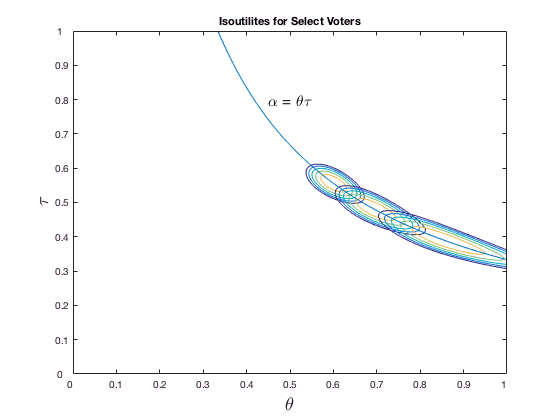

concavity_check = true;
if concavity_check == true
  run('utilities.m')
end

## Switch to true to calculate and plot the Reaction Functions

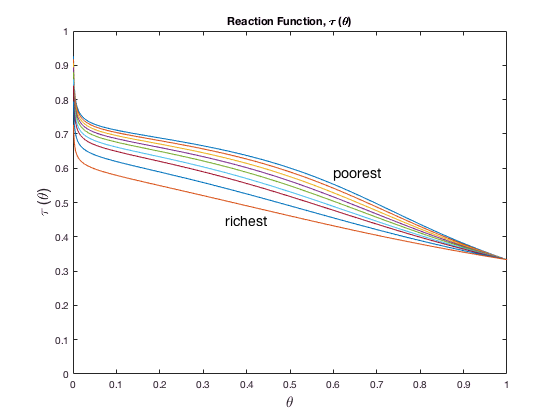

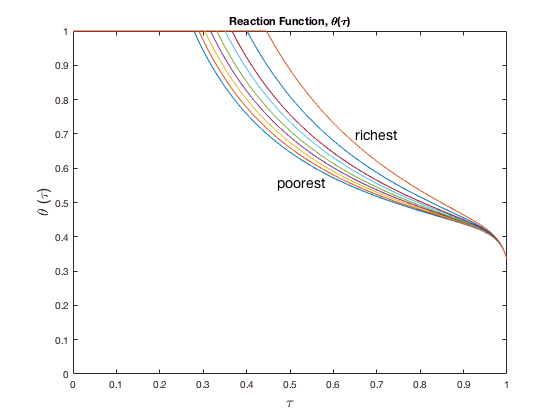

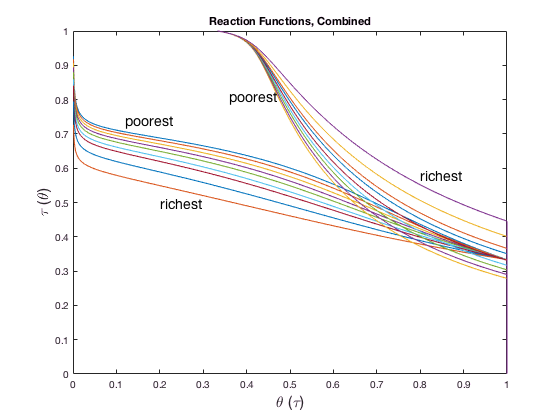

reactions = true;
if reactions == true
  run('reaction_fns.m')
end

## Switch to true to calculate and plot the Pareto Optimum set

pareto = true;
if pareto == true
  run('pareto_optimum.m')
end

## Switch to true to simulate and plot One-Dimensional Elections

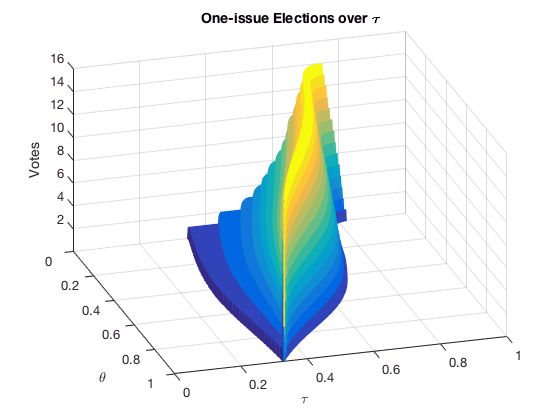

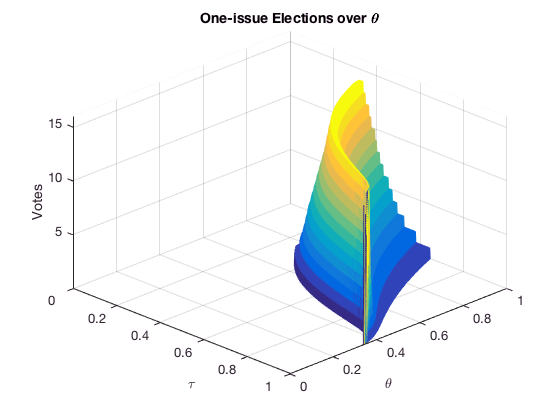

part_election = true;
if part_election == true
  run('partial_elections.m')
end

## Switch to true to simulate and plot Two-Dimensional (general) Elections

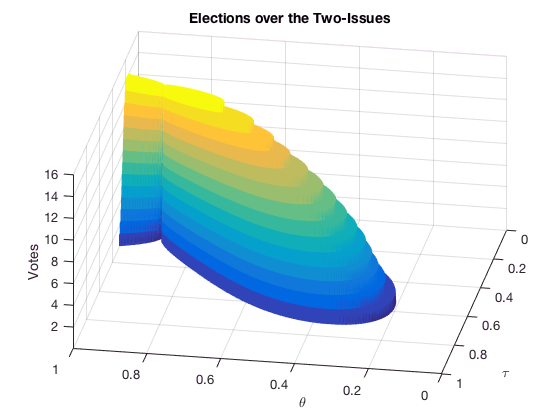

gen_election = true;
if gen_election == true
  run('gral_election.m')
end

## Switch to true to calculate the Policy Effects of the electoral outcome

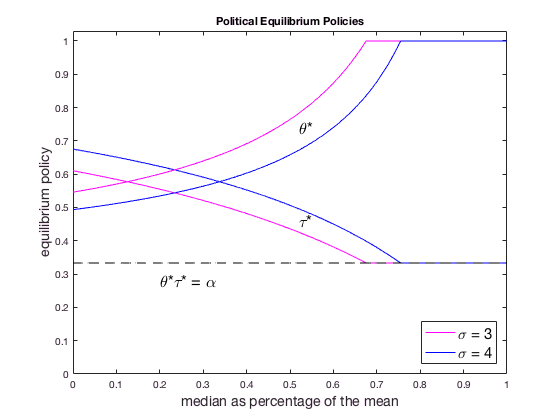

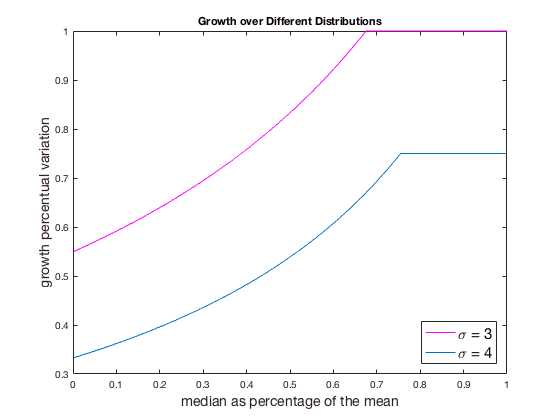

policyfx = true;
if policyfx == true
  run('policy_effects.m')
end

## Switch to true to calculate the most preferred platform of each voter

Will find the platform most prefered by each voter. By default, it tests the same agents for which the reaction functions were plotted. Change n_voters below to alter the number of voters. This section will also yield the results reported in section 3.2 of the paper, by calling best_platforms(5,:). 

get_preferred_platforms = false;
if get_preferred_platforms == true
  run('params.m')
  run('dist_gen.m')
  n_voters = 9;
  prod = quantile(l_dist, n_voters);
  [val, mean_idx] = min(abs(prod - mean(l_dist)));
  prod(mean_idx) = mean(l_dist);
  run('preferred_platforms.m')
  best_platforms = ones(n_voters,2);
  best_platforms(:,1) = taup;
  best_platforms(:,2) = thetap;
 end